# T1 and T2 signals

For certain pulse sequences we can work out formulae for the expected signal amplitudes, and in particular how these signals depend on the sequence parameters.  This script shows the expected signals from a Spin Echo sequence  as we vary TR and TE. 

The signals also depend on the T1 and T2 values of the substrate, of course. 

The relationship between  these terms is called the **'Signal Equation'.**

## Tissue properties

We start by setting up the tissue parameters.

PD = 1;     % Proton density
T1 = 1.330; % gray matter at 3T (https://www.ncbi.nlm.nih.gov/pubmed/10232510)
T2 = 0.080; % gray matter at 3T (https://www.ncbi.nlm.nih.gov/pubmed/10232510)
k  = 1;     % Other scale factors

## Spin Echo signal equation

Different sequences have different parameters and equations.  See the [CNI wiki page for a few equations](https://cni.stanford.edu/wiki/MR_Signal_Equations).

The signal equation for the Spin Echo sequence is


$$S=k*\mathrm{PD}*\left(1-\mathrm{exp}\left(-\frac{\mathrm{TR}}{\mathrm{T1}}\right)\right)*\mathrm{exp}\left(-\frac{\mathrm{TE}}{\mathrm{T2}}\right)$$


## T1 weighted  (Short TR, short TE)

Recall from the lecture that as we change the value of the TR and TE parameters, the signals we recover are dominated more by the T1 value or the T2 value.  When we have a short TR and short TE, the signal is T1 weighted.  By long and short, we mean with respect to the T1 and T2 times of the substrate.  In this case, we set TR and TE to a fraction of the T1 and T2 times.

% We fix the TR and TE values of the sequence (secs)
TR = T1/5; 
TE = T2/4;

% A variable of time that we use in the calculations below
tSteps = 0.01:0.01:4;

Suppose we fix the sequence parameters and measure what the signal will be for substrates with different T1 values. 

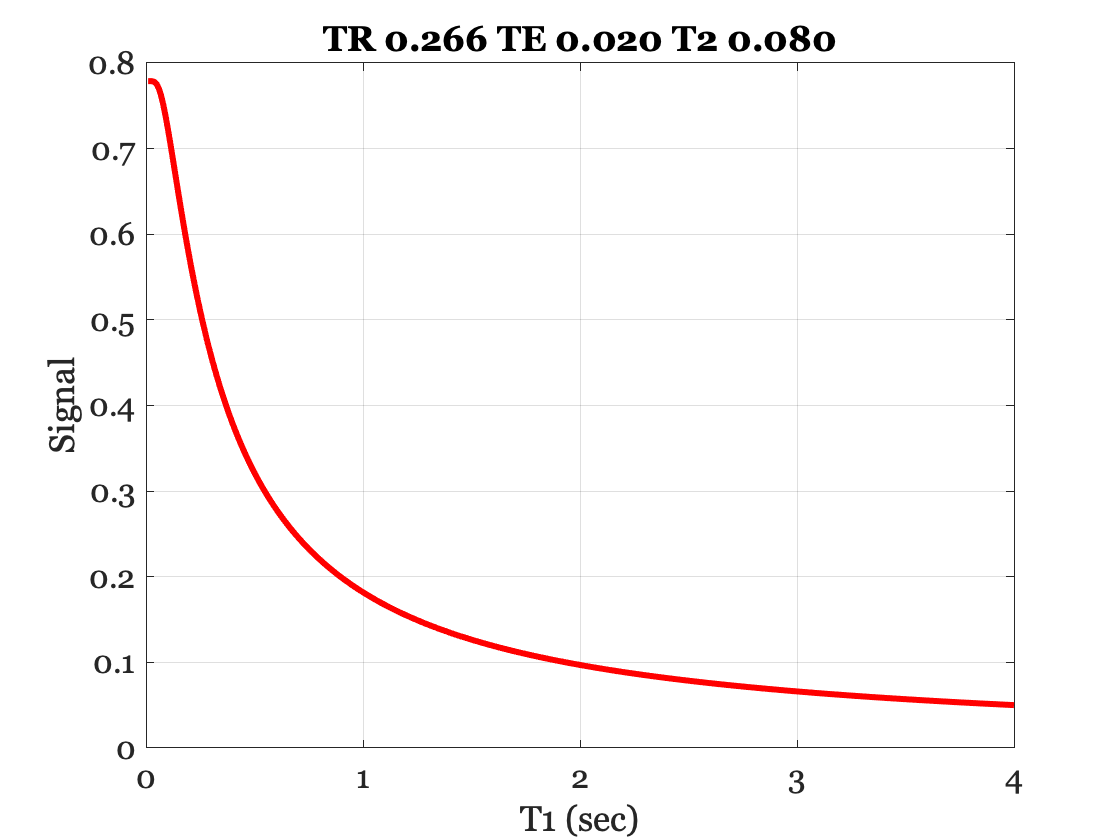

t1wSignal  = k * PD * (1 - exp(-TR ./ tSteps)) * exp(-TE / T2);
figure; plot(tSteps, t1wSignal,'LineWidth', 3); grid on;
xlabel('T1 (sec)'); ylabel('Signal');
title(sprintf('TR %4.3f TE %4.3f T2 %4.3f',TR, TE, T2));

Notice that as T1 grows, the signal decreases.  That is a reason for the convention that for T1-weighted data the image intensity  is inversely related to the T1 value, not proportional to the T1 value!

Now, fix T1 and vary the pulse sequence parameter, TR. This measures how the signal recovers over time.

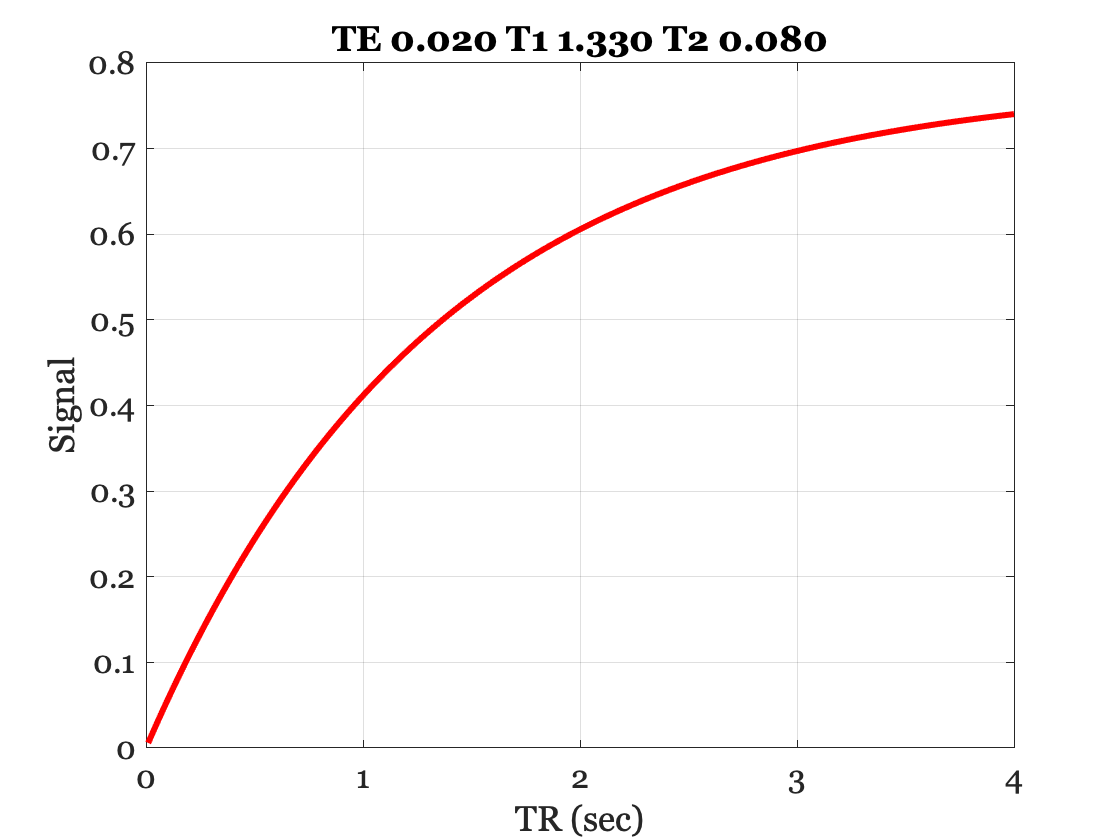

t1Recovery = k * PD * (1 - exp(-tSteps ./ T1)) * exp(-TE / T2);
figure; plot(tSteps, t1Recovery,'LineWidth', 3); grid on;
xlabel('TR (sec)'); ylabel('Signal');
title(sprintf('TE %4.3f T1 %4.3f T2 %4.3f',TE, T1, T2));

## T2 weighted image (Long TR, long TE)

We set the TR and TE values to be relatively long.

TR = 3*T1;  
TE = 2*T2;

tSteps = 0.01:0.01:0.5;

For these sequence parameters see how the signal depends on T2.  

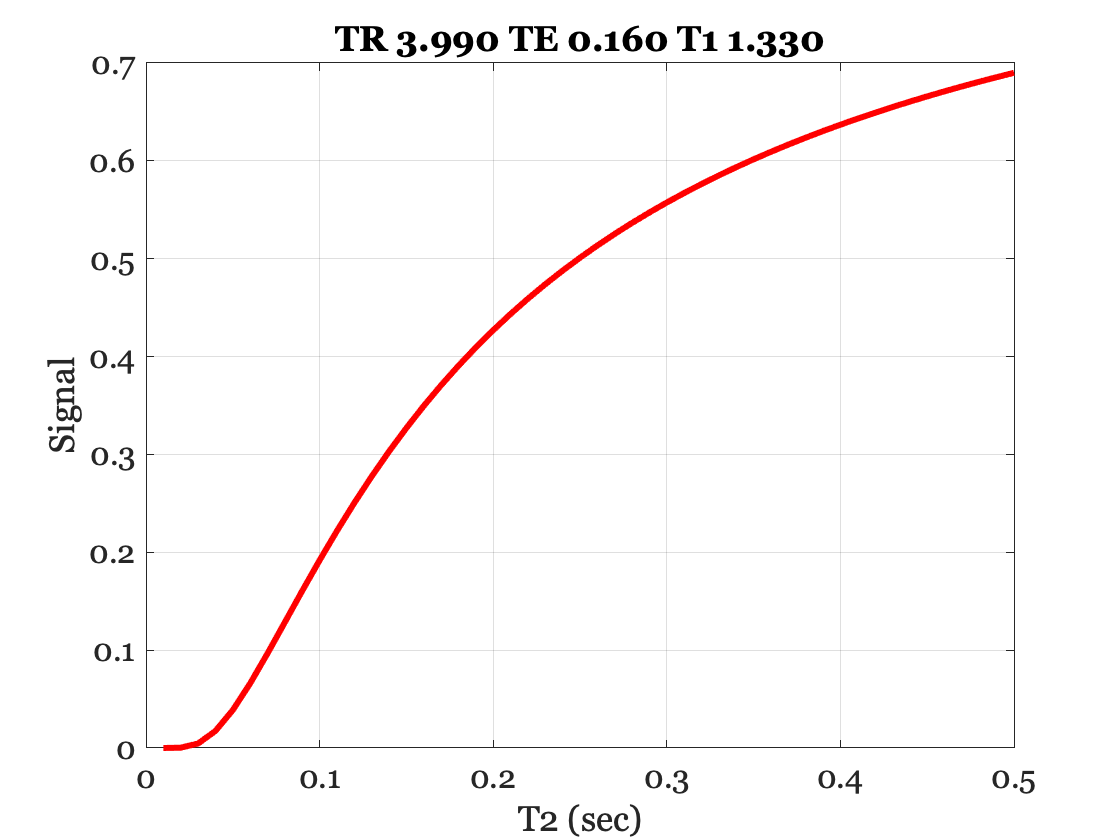

t2wSignal = k * PD * (1 - exp(-TR / T1)) * exp(-TE ./ tSteps);
figure; plot(tSteps, t2wSignal,'LineWidth', 3); grid on;
xlabel('T2 (sec)'); ylabel('Signal');
title(sprintf('TR %4.3f TE %4.3f T1 %4.3f',TR, TE, T1));

Unlike the T1 case, the signal intensity increases with T2.  That is why the T2-weighted images are brighter where T2 is larger.

Now, fix T2, and vary the sequence parameter TE. You get a measure of how the signal decays over time.

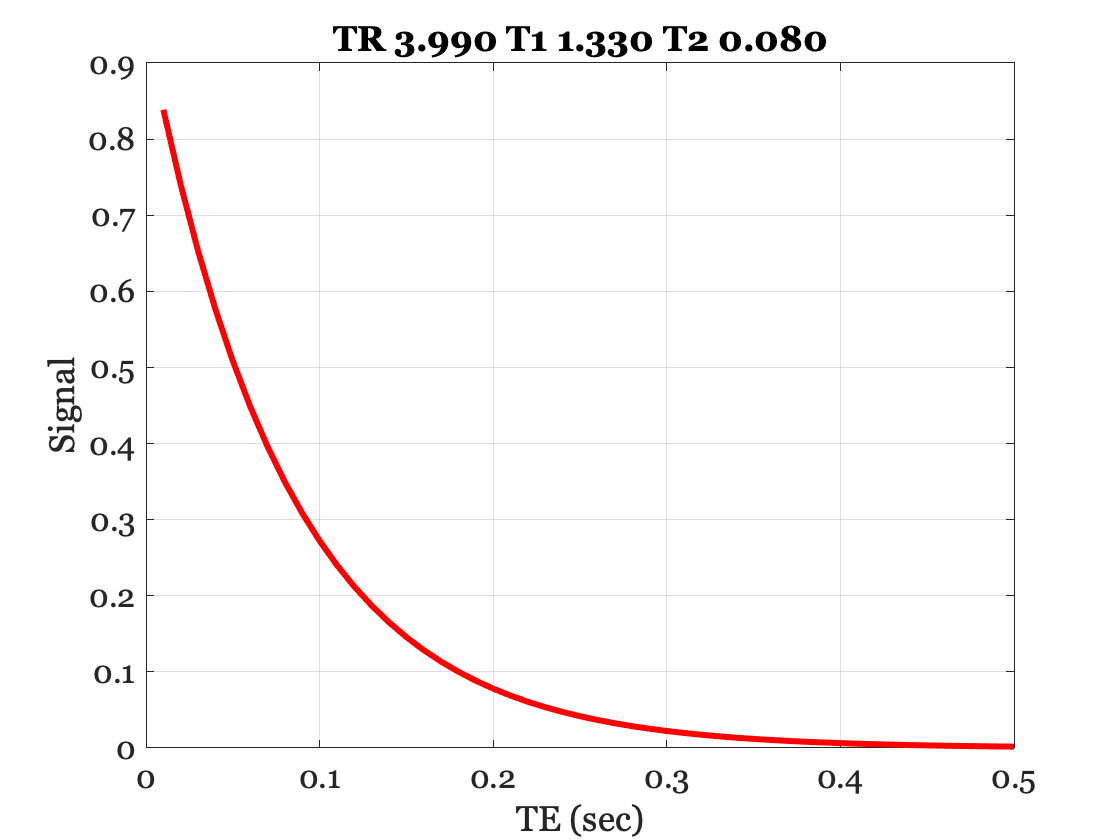

t2decay   = k * PD * (1 - exp(-TR ./ T1)) * exp(-tSteps / T2);
figure; plot(tSteps, t2decay,'LineWidth', 3); grid on;
xlabel('TE (sec)'); ylabel('Signal');
title(sprintf('TR %4.3f T1 %4.3f T2 %4.3f',TR, T1, T2));